# Final Project: Detecting Cars in a Noisy Video

## Project Overview

### Introduction to the final project:

#### Scenario:  A company hired you to check the traffic volume infront of theri office:

Specifics. Count number of cars in each frame:

**Steps:**

- **Preprocess the video by removing the noise and grayscaling it.**

- **Isolate the cars in the eeach frame by a binary mask the segments from the background.**

- **Calculate region properties, and analyse the results for the entire video.**

1158*518

ans = 599844

## Section 1: Preprocessing the video

vIn = VideoReader("RoadTraffic.mp4");

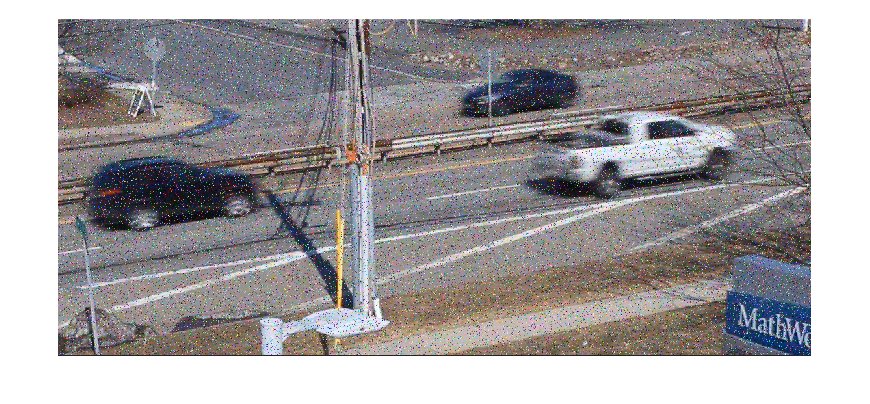

image = read(vIn,152);
imshow(image)

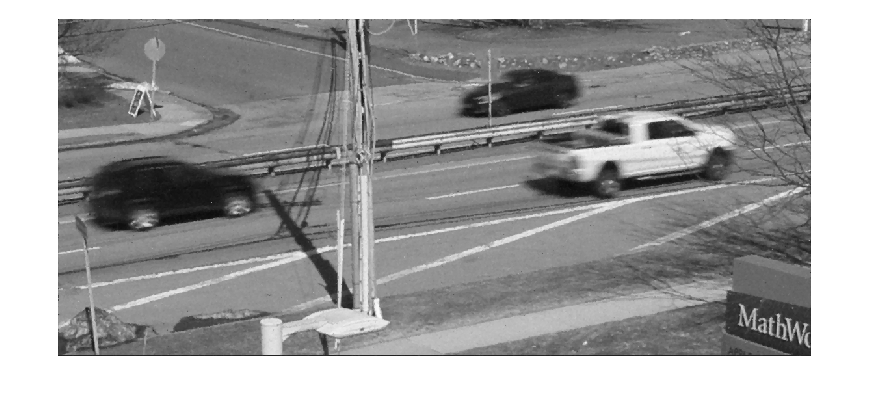

imshow(removeNoiseAndGray(image))

## Section 2: Isolating the cars

### Get background representative frame: 

Frames with no cars are: 1-5,28-60, 86-93, 118-143

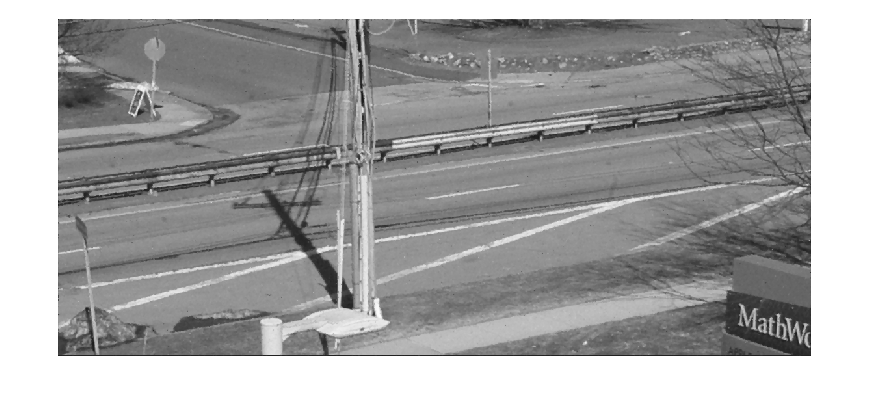

a = [1:5];
b = [28:60];
c = [86:93];
d = [118:143];
back_idx = cat(2,a,b,c,d);
background = im2double(removeNoiseAndGray(read(vIn,back_idx(1))));
for i = 2:length(back_idx)
    background = background + im2double(removeNoiseAndGray(read(vIn,back_idx(i))));

end
background = background/length(back_idx);

imshow(background)

frame = read(vIn,22);
frame = removeNoiseAndGray(frame);
frame = im2double(frame);
frameDiff = abs(frame - background);
%montage({frameDiff,segmentCar(frameDiff)})
iii = segmentCar(frameDiff);
%imshow(frame)
%imshow(frameDiff)
max(max(frameDiff))

ans = 0.7279

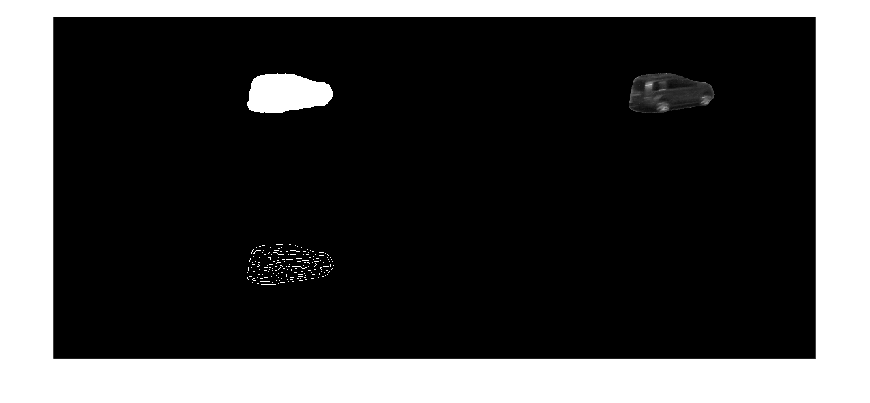

edgeimg = frame;
edgeimg(~iii) = 0;
montage({iii, edgeimg, edge(imgaussfilt(edgeimg,3),"canny")})

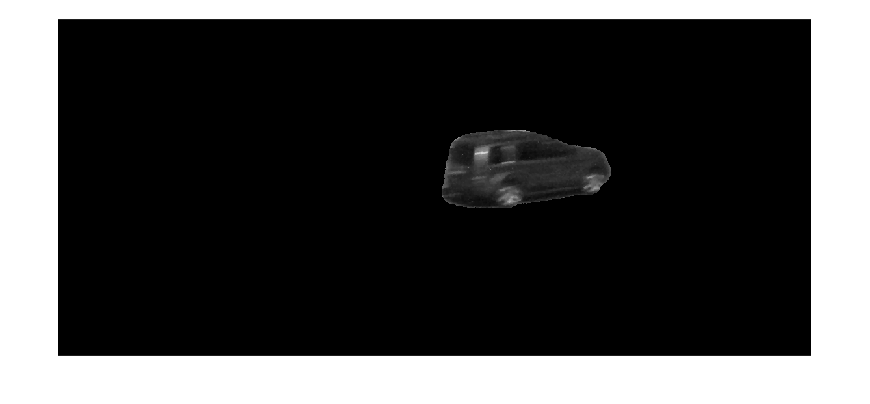

imshow(edgeimg)

nnz(iii)

ans = 24564

Testing video

vOut = VideoWriter("trafficSegment.mp4", "MPEG-4");
vOut.FrameRate=10;
vIn = VideoReader("RoadTraffic.mp4");

nFrames = vIn.NumFrames;
open(vOut)

for i =1:nFrames
    img = readFrame(vIn);

    frame = removeNoiseAndGray(img);
    frame = im2double(frame);
    frameDiff = abs(frame - background);
    %montage({frameDiff,segmentCar(frameDiff)})
    bw = segmentCar(frameDiff);

    %frame = imfuse(im2uint8(img),im2uint8(bw),"montage");
    bw = im2uint8(bw);
    writeVideo(vOut,bw);


    time = vIn.CurrentTime;
end

close(vOut)
vIn.CurrentTime = 0;

## Section 3: Calculating region properties

NumberRegions = [];
MeanRegionSize = [];
TotalRegionSize = [];



vIn = VideoReader("RoadTraffic.mp4");

nFrames = vIn.NumFrames;


for i =1:nFrames
    img = readFrame(vIn);

    frame = removeNoiseAndGray(img);
    frame = im2double(frame);
    frameDiff = abs(frame - background);
    %montage({frameDiff,segmentCar(frameDiff)})
    bw = segmentCar(frameDiff);

    %frame = imfuse(im2uint8(img),im2uint8(bw),"montage");
    
    props = regionprops(bw, {'Area'});
    props = struct2table(props);

    
        NumberRegions = [NumberRegions; size(props,1)];
        MeanRegionSize = [MeanRegionSize; mean(props.Area)];
        TotalRegionSize = [TotalRegionSize; sum(props.Area)];
    

    time = vIn.CurrentTime;

end

vIn.CurrentTime = 0;

regionData = table(NumberRegions,MeanRegionSize,TotalRegionSize)

sum(regionData.NumberRegions>0)

ans = 151

regionData(152,"TotalRegionSize")

ans = table
    TotalRegionSize
    _______________

         62245     


mode(regionData.NumberRegions)

ans = 1

sum(regionData.TotalRegionSize)/sum(regionData.NumberRegions)

ans = 1.6081e+04

function im = removeNoiseAndGray(RGB)


im = rgb2gray(RGB);
im = medfilt2(im);


end

function bw = segmentCar(diffIntensity)
bw = diffIntensity>0.2;

%% First, we will extract the region around the pole. If there are true pixels on both sides of the pole, we will join them.

bw = imclose(bw, strel("disk",3,0));
bw_pole = bw(38:445,445:490);
bw_pole = imclose(bw_pole, strel("line",45,10));

%% second, we will extract the region around the tree. If there are true pixels there, we will join them.
bw_tree = bw(97:231,999:1158);
bw_tree = imclose(bw_tree, strel("disk",45,0));




%% JOin all parts
bw(38:445,445:490) = bw_pole;
bw(97:231,999:1158) = bw_tree;
%bw = imopen(bw,strel("disk",3));


bw = imclose(bw, strel("disk",20,0));
bw = imopen(bw, strel("disk",20,0));
bw = imopen(bw, strel("disk",3,0));
end
